# **Lab 2:  Spectral analysis and Detection theory**

**Statistical Signal Processing (5CTA0) - Lab Assignment**

Lecturers: Simona Turco (Flux 7.076), Nikoloska, Ivana (Flux 7.067)

Assistants: Yizhou Huang, Ben Luijten, Agata Barbagini, Xueting Li

**Students (Name + IDs): Roy van Doorn (1484982)**

**Group #: 12**

## General info and guidelines

To complete and submit the Labs:

`•`All students must register on Canvas.

`•`Each lab will be carried out in groups of 4 students, which must register on Canvas.

`•`All information and data will be available on Canvas.

`•`Each group must carry out all assignments of the Lab and hand in a report for each Lab.

`•`**The report is obtained by exporting this matlab live script as pdf. This is the only file that you need to provide.**

`•`**Sometimes, runing the code within livescript might be slow. You may consider to first implment and test your code in a seperate .m file, and copy the code to livescript in the end. **

`•`The report must be submitted through Canvas.

`•`In case of problems, the labs can alternatively be submitted by emailing the lab assistants. The email address are available on Canvas.

`•`The report must be accompanied by the peer-review form, which is used to provide an indication of the contribution of each student in the group. The link to the peer review form is available on Canvas.

`•`If plagiarism is detected, the Lab will be judged with 0 points.

Below, some useful tips for working with MATLAB and for producing a neat Lab report:

`•`Make use of comments to divide the code in sections and facilitate its understanding.

`•`Use the command `doc or` `help` to learn how to use a specific MATLAB functions (e.g.`doc stem`).

`•`Make sure that all your graphs are easily readable, even when printed in black and white. Use for this purpose the options of the plot/stem function to properly increase the dimension and/or change the marker symbols, for example:

`•`Make sure that all your graphs have their axes properly labeled and a legend when several signals are plotted on the same graph. Also, make sure that all the text is readable. Below some useful commandsfor these purposes:

## Credits and deadlines

Each Lab counts for 15% of the final grade, for a total of 30%. The remaining 70% is determined by the final written exam. 

Please submit this lab on Canvas by 30/10/22 at 23:59.

## Analysis of seismological data - Introduction

**Note**: you will need the *Econometric Toolbox*, the *Signal Processing Toolbox* and the *Statistics and Machine Learning Toolbox* to carry out this assignment.

Seismology is the study of the origin, propagation, and effects of earthquakes, and in general of elastic waves through the Earth. The study of these phenomena gives information about different processes relevant in geography and geophysics. For example, the propagation of seismic waves reveals the structure and composition of Earth's inner layers, it is closely related to volcanic activity and tsunamis, and it can help localizing water and oil reservoirs. Moreover, the study of the seismic activity in a region and its associated risks is a fundamental task when planning buildings constructions and maintenance. Propagation of seismic waves from the epicenter to the surface is a quite complex phenomenon, characterized by multiple reflections as the wave traverls trough different materials with different densities. The image below shows a simplified diagram of Earth's inner layers:

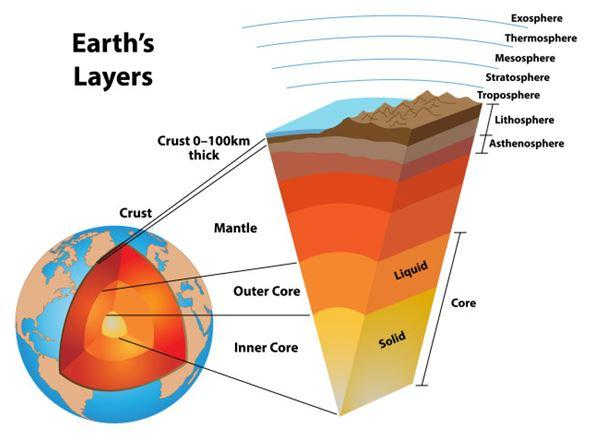

Seismic waves are detected using an instrument called seismometer. Originally, the soil displacement was recorded by tracing the displacement of the ground with respect to a hanging weight. In modern seismology, this system is replaced by a very accurate negative-feedback electrical device designed to keep a small mass in place through electromagnetic force. The force applied is proportional to the current passing trough a coil, which is sampled and recorded. Thus, knowing the current and the mass, the applied force can be derived, hence the ground acceleration, velocity, and displacement. Seismic observatories implement multiple sensors oriented along three orthogonal directions. In order to detect small ground movements, the measurements can be also amplified.

There are mainly two types of waves: P-waves (primary or pressure waves), longitudinal elastic waves -- compression and expansion are parallel to the direction of propagation; and S-waves (shear waves), transverse waves -- compression and expansion are orthogonal to the direction of propagation. P-waves travel faster than S-waves through the Earth, thus they are detected first by the seismometer. The image below shows graphically the two types of waves.

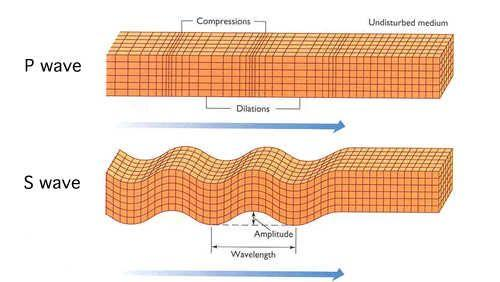

Spectral estimation is a powerful tool for the analysis of seismic events, as source parameters are mainly derived in the frequency domain. For an intuitive understanding: when we place a ruler at the edge of a table and strike its end, the frequency of the oscillation is inversely proportional to the length of the ruler sticking out of the table; similarly, the corner frequency in the spectrum of the seismic event is inversely proportional to the dimension of the source of the event. Other source parametes like moment, energy, and stress are also derived from frequency characteristics [1, 2]. 

In this assignment, we'll use seismic data to develop a practical understanding of non-parametric and parametric spectral estimation techniques and detection theory.

The provided data was retrieved from the EarthScope Consortium databases [3].

## Assignment 1:  Stationarity and Ergodicity

Before we start dealing with spectral estimation, it is important to analyze our signals from a statistical point of view. Namely, we must determine the stationarity and ergodicity of the process, in order to apply estimation techniques correctly.

Our dataset comprises an earthquake event which took place in Japan during 2024. Specifically, we are looking at recordings taken at the seismic observatory located in Matsushiro [4]. The time series contains the (amplified) ground displacement due to P- and S-waves, measured by one sensor, sampled at 40 Hz, in arbitrary units due to the amplification. The seismic observatory records ground displacement data continuously, and the given data is extracted from the continuous recording starting approximately one minute before P-wave arrival and ending three minutes after.

**QUESTION 1a**

Load Assignment1.mat and plot its time series. Do you expect the processes to be wide-sense stationary? What about ergodicity?

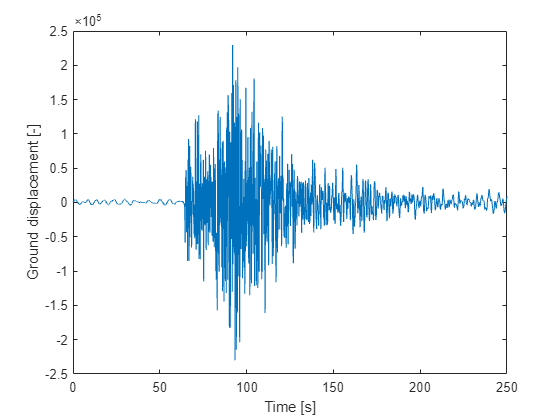

load Assignment1.mat
time_vector = (0:length(Event)-1)*1/40;

figure()
plot(time_vector, Event)
xlabel('Time [s]')
ylabel('Ground displacement [-]')

**ANSWER**

*Wide-sense stationary*

The process is not wide-stationary, because the variance and mean change over time. The variance around 100s is much higher then the variance around 200s for example. Furthermore the correlation between two measuring points is dependent on when the earthquake started, not only on the time lag. This means that the mean and the variance are not constant over time, and the autocovariance function depends on more than just time lag, and thus the signal is not wide-sense stationary.

*Ergodicity*

The signal is not ergodic as the average mean and variance of this recording might not be the same for other recordings. This is because earthquakes hapen at different strengths and move the earth in different intensities. An earthquake at a higher strength will have a higher varaiance in its data signal for example. 

**QUESTION 1b**

Let's investigate stationarity more in detail. A common approach for this analysis is to split signals into segments using different lengths, and determine the maximum length for which the segments can be considered to be stationary. 

We will split the signal into segments, compute the mean and variance for each segment, and plot them as a funciton of time. Test segments of lengths [2.5, 5, 10, 20] seconds, and create a subplot containing the resulting means and variances as a function of time. Describe what you observe. Do you think it is resonable to use the maximum length?  

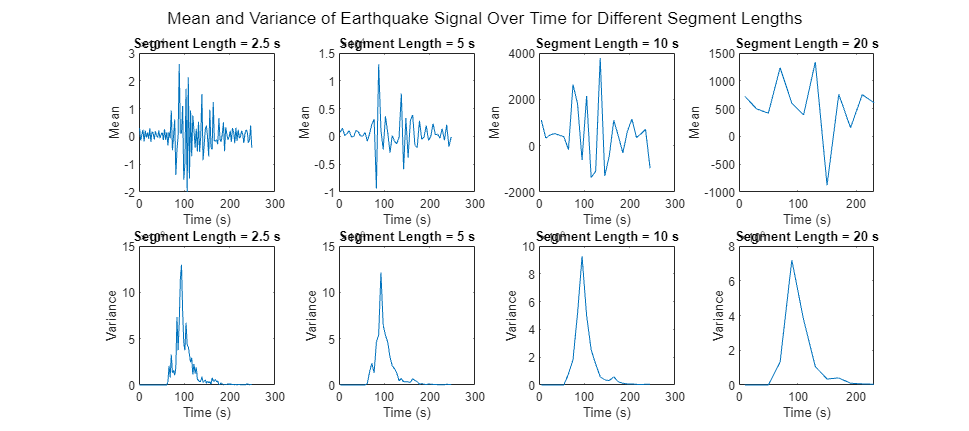

Fs = 40;

% Define segment lengths in seconds
segment_lengths = [2.5, 5, 10, 20];
segment_samples = segment_lengths * Fs;
figure('Position', [100, 100, 1800, 800]);

% Loop through the segment lengths
for i = 1:length(segment_lengths)
    seg_len = segment_samples(i); 
    num_segments = floor(length(Event) / seg_len);  
    
    % Initialize arrays to store mean and variance for each segment
    means = zeros(1, num_segments);
    variances = zeros(1, num_segments);
    time_points = zeros(1, num_segments);  % For tracking time of each segment
    
    for j = 1:num_segments
        segment_data = Event((j-1)*seg_len + 1 : j*seg_len);
        means(j) = mean(segment_data);
        variances(j) = var(segment_data);
        time_points(j) = (j-0.5) * seg_len / Fs;
    end
    
    % Create subplot for the current segment length
    subplot(2, length(segment_lengths), i);  % Top row for means
    plot(time_points, means);
    xlabel('Time (s)');
    ylabel('Mean');
    title(['Segment Length = ', num2str(segment_lengths(i)), ' s']);
    
    subplot(2, length(segment_lengths), i + length(segment_lengths));  % Bottom row for variances
    plot(time_points, variances);
    xlabel('Time (s)');
    ylabel('Variance');
    title(['Segment Length = ', num2str(segment_lengths(i)), ' s']);
end

% Add a title to the entire figure
sgtitle('Mean and Variance of Earthquake Signal Over Time for Different Segment Lengths');

**ANSWER**

The change in mean and variances reduces with higher segment lengths. The signal becomes smoother the higher the segment lenght becomes. When using the maximum segment length (20 seconds) the system might be too smooth to capture the intensity of the earthquake and might result in a loss of information. Depending on the goal of the data analysis this might hurt the overall outcome of the study.

**QUESTION 1c**

One possible source of non-stationarity in the signal is the presence of a trend: a specific behavior that the samples follow over time. One way to remove the trend from a signal is to apply differentiation: it helps remove a trend from a signal by focusing on changes in the signal rather than its overall level. Since trends are typically slow variations, the derivative emphasizes the short-term fluctuations, effectively reducing the impact of long-term trends. Differentiate the signal and plot it. What do you observe? 

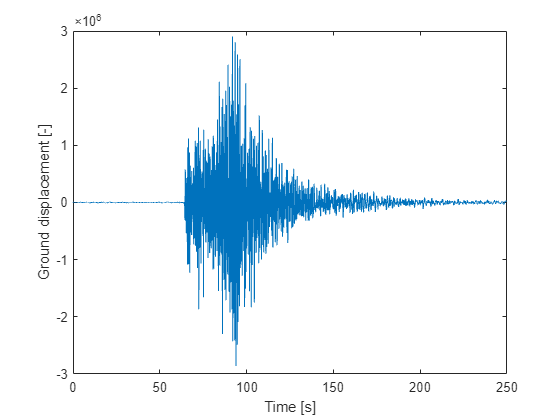

dt = 1 / 40;        
diff_event = diff(Event) / dt;
time_vector = (0:length(diff_event)-1)*1/40;

figure()
plot(time_vector, diff_event)
xlabel('Time [s]')
ylabel('Differentiated ground displacement [-]')

**ANSWER**

The amplitude of the signal gets even higher when differentiated. This can be explained by the fact that the peaks in the original signal are very short and very high, differentiating the signal highlights the big changes in displacement in a short period of time. This proves that there is not much of a trend in the signal, but more a rapid flucuation in ground displacement when the earthquake hits. 

**QUESTION 1d**

Repeat exercise 1b using the detrended version of the signal. What do you observe?

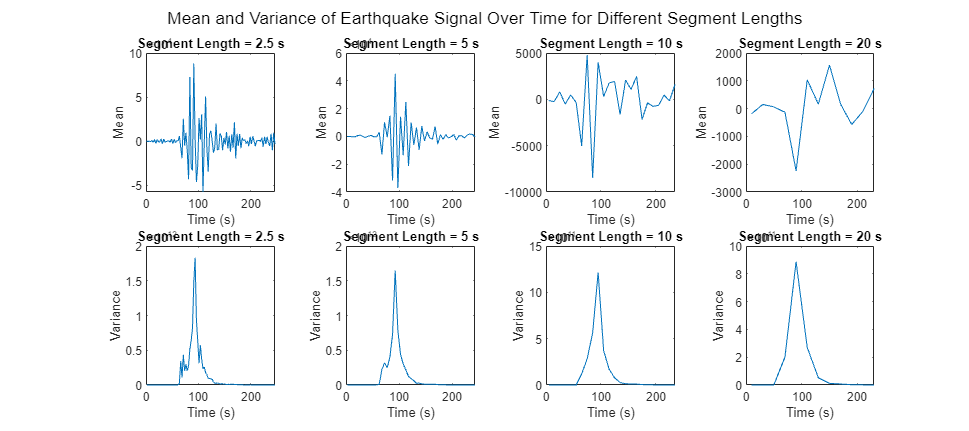

Fs = 40;

% Define segment lengths in seconds
segment_lengths = [2.5, 5, 10, 20];
segment_samples = segment_lengths * Fs;
figure('Position', [100, 100, 1800, 800]);

% Loop through the segment lengths
for i = 1:length(segment_lengths)
    seg_len = segment_samples(i); 
    num_segments = floor(length(diff_event) / seg_len);  
    
    % Initialize arrays to store mean and variance for each segment
    means = zeros(1, num_segments);
    variances = zeros(1, num_segments);
    time_points = zeros(1, num_segments);  % For tracking time of each segment
    
    for j = 1:num_segments
        segment_data = diff_event((j-1)*seg_len + 1 : j*seg_len);
        means(j) = mean(segment_data);
        variances(j) = var(segment_data);
        time_points(j) = (j-0.5) * seg_len / Fs;
    end
    
    % Create subplot for the current segment length
    subplot(2, length(segment_lengths), i);  % Top row for means
    plot(time_points, means);
    xlabel('Time (s)');
    ylabel('Mean');
    title(['Segment Length = ', num2str(segment_lengths(i)), ' s']);
    
    subplot(2, length(segment_lengths), i + length(segment_lengths));  % Bottom row for variances
    plot(time_points, variances);
    xlabel('Time (s)');
    ylabel('Variance');
    title(['Segment Length = ', num2str(segment_lengths(i)), ' s']);
end

% Add a title to the entire figure
sgtitle('Mean and Variance of differentiated Earthquake Signal Over Time for Different Segment Lengths');

**ANSWER**

As could be expected after the results in exercise c. The amplitude of the mean and variance plots has increased for each of the segment lengths. Similar to the answer in exercise c, this proves that there is not really a trend in the signal, more a high fluctuation in ground displacement when the earthquake hits. This is also seen in the variance plots, where the variance remains close to 0 except for when the earthquake hits, then the variance spikes to great heigts. 

**QUESTION 1e**

Given the investigated statistical properties of the process, does it make sense to estimate its power spectral density using the whole time series? What if we apply differentiation?

**ANSWER**

Since the signal is not stationary it does not make sense to estimate the power spectral density of the whole time series. This does not improve when differentiating the signal, as differentiation only seems to amplify the high frequency fluctuations that are present in the time series.

## **Assignment 2: Non-parametric spectral estimation**

In the first part of the assignment, we assessed the stationarity and ergodicity of the process. We can now proceed to inspect some techniques to estimate its power spectral density. 

First, we will look into the non-parametric spectral estimation techniques.

**QUESTION 2a**

What are the "raw" estimators for the power spectral density? What other methods can be implemented to improve their performance with respect to bias and variance?

**ANSWER**

...

As discussed during the lectures, dividing the signal into segments through a window function and averaging is a key idea behind the improved estimators. When stationarity is verified, statistical and frequency characteristics are the same at each point in time, allowing averaging to decrease the variance of the estimation.

On the other hand, when the process cannot be considered stationary, its properties change over time and averaging between different segments of a realization does not converge to a meaningful quantity. From this consideration, the idea of the spectrogram is derived: PSD estimation cannot be performed over the whole signal, but it can be performed over each segment individually to obtain a time-dependent frequency characterization. The spectrogram is a time-dependent PSD estimation. In practice, a signal is divided into segments that are small enough to be considered stationary, and the Fourier transform is computed for each segment. The *Short-Time Fourier Transform* (STFT) is defined as follows:

$S(t,\omega) = \int_{-\infty}^{+\infty}x(t')g
(t-t')e^{j\omega t'}dt'$,

where $x\left(t^{\prime } \right)$ is a non-stationary signal, $g\left(t-t^{\prime } \right)$ is a window function, and $S\left(t,\omega \right)$ is the resulting time-dependent Fourier transform. Note how the integration is performed over the variable $t^{\prime }$, whereas the variable $t$ indicates where the window is located in time. The spectrogram is the plot of $|S\left(t,\omega \right)|^2$ in both frequency and time. In MATLAB, the discrete-time version of this formula is already implemented in the function *spectrogram. *The image below, extracted from [3], illustrates the operations performed:

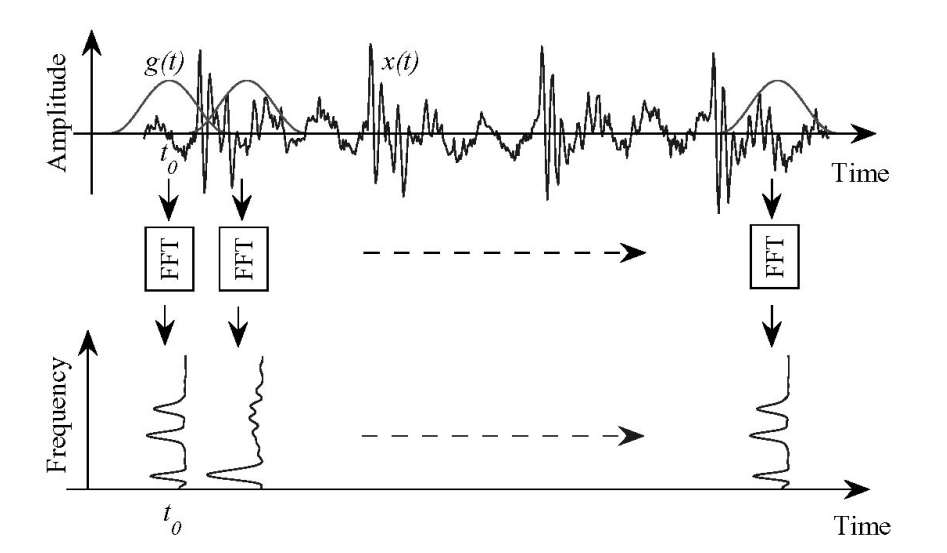

Another important detail to keep in mind when perfroming time-dependent frequency estimation is the trade-off between time resolution and frequency resolution: if we take a window that includes the whole signal, we won't be able to identify any time-varying characteristic, whereas if the segments are too small we won't capture low-frequency components.

In the image below, the spectrogram of an audio signal is provided as an example. It can be observed that over time, the dominant frequency (also called pitch) changes sinusoidally between a maximum and a minimum frequency. This sinusoidal variation of the pitch is the iconic feature of alarm sounds.

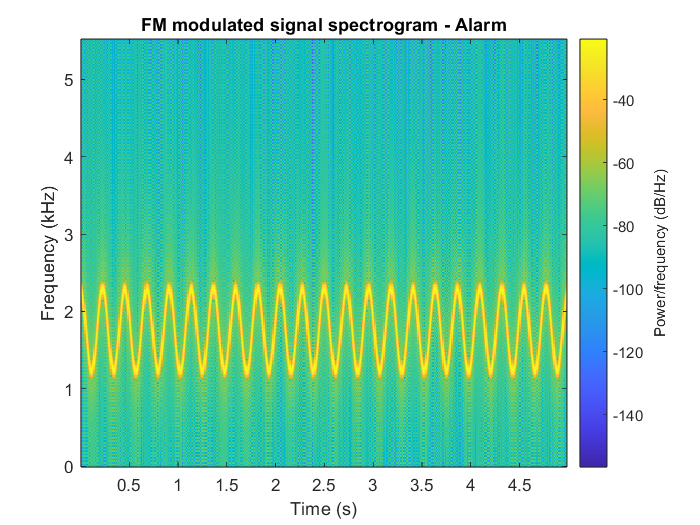

As observed in Assignment 1, determining the optimal window length is not an easy task and it strictly depends on the data under analysis. For the following tasks, you can divide the time series in segments of 5 seconds.

**QUESTION 2b**

Using the MATLAB *spectrogram* funciton, analyze the time-dependent power spectral density of the signal. What part of the signal takes the largest power density across a wider frequency range? Is it an expected result?

**Hint: **look into the function documentation to understand its inputs, and keep in mind that there are dedicated MATLAB implementations for the window functions in the Signal Processing Toolbox.

% your code goes here 

**ANSWER**

...

**QUESTION 2c**

The windowing operation can be performed using different kinds of window functions. Compare the rectangular window, the Hann window, and two other windows of your choice in terms of spectral leakage and spectral resolution. Make sure that all windows have the same length.

**Hint: **you can use the MATLAB *freqz* function.

% your code goes here 

**ANSWER**

...

**QUESTION 2d**

Create a plot in which you compare the effects of the four window functions: choose one segment from the event, apply the window and plot the power spectral density for each window. Describe what you observe.

% your code goes here 

**ANSWER**

...

**QUESTION 2e**

Plot the spectrogram of the signal again using all the windows mentioned earlier and observe your results. Which window function do you think is more appropriate for the spectral estimation of seismic data?

% your code goes here 

**ANSWER**

...

## **Assignment 3: Parametric spectral estimation**

We will now address the problem of spectral estimation of non-stationary processes using parametric approaches. Parametric approaches are more flexible as they don't assume any periodicity, but they need an assumpion on the structure of the data. We are going to use ARMA models together with the segment approach.

An ARMA(p,q) model is characterized by two parts, namely, an autoregressive part of order p and a moving-average part of order q. The autoregressive part describes the relation between the output and past output values, whereas the moving-average part describes the relation between the output and past input values. For the task of spectral estimation, the input for an ARMA model is assumed to be white Gaussian noise with zero mean. If needed, the ARMA(p,q) model can be further generalized by adding a constant to take into account processes with non-zero mean: this is what is done by the MATLAB function *arima(p,D,q). *This function also allows to take into account the degree of differentiation *D *required to make the signal stationary, but for our analysis we can just set *D=0*.

For example, the command *arima(3,0,2) *will generate the following model:

$x\left\lbrack k\right\rbrack =c+i\left\lbrack k\right\rbrack +b_1 i\left\lbrack k-1\right\rbrack +b_2 i\left\lbrack k-2\right\rbrack +a_1 x\left\lbrack k-1\right\rbrack +a_2 x\left\lbrack k-2\right\rbrack +a_3 x\left\lbrack k-3\right\rbrack$.

Note that the autoregressive coefficients are defined with opposite sign with respect to the definition given in the course.

Once the model orders p and q have been decided, the model parameters ${\left\lbrace a_k \right\rbrace }_{k=1}^p$ and ${\left\lbrace b_k \right\rbrace }_{k=1}^q$, the input noise variance $\sigma_n^2$ and the constant $c$ can be estimated from the data.

How can we decide which are the optimal model orders? Different criteria are available in the literature. In this assignment, we will consider Akaike's information criterion, defined as follows:

$\textrm{AIC}\left(K\right)=N\;\ln \left(\sigma_K^2 \right)+2K$,

$K=p+q+2$,

where $N$ is the number of samples used to perform the estimation, $K$ is the total number of estimated parameters, and $\sigma_K^2$ is the variance of the residual error. The best model is the one achieving the lowest AIC. Note that the AIC can take both positive or negative values due to the logarithm.

Depending on the number of samples, the AIC might lead to overfit the data. Overfit can be avoided by penalizing the model complexity. The corrected Akaike's information criterion includes an additional term to achieve this:

$\textrm{AICc}\left(K\right)=\textrm{AIC}\left(K\right)+\frac{2K\left(K+1\right)}{N-K-1}$.

In the literature, many model orders have been tested on multiple earthquake events. It turns out that different model orders and different parameter values reveal information about the physics underlying the seismic events, and parameters estimated from data recorded in a specific region can be used to characterize Earth's inner layers in that region. In particular, ARMA(2,1) processes model linear damped oscillator systems, and ARMA(4,1) processes can be approximated as two of such systems acting in series. The estimated parameters relate to the physical characteristics of the two oscillators, namely natural frequencies and damping factors [4]. 

For this assignment, you can again divide the time series into segments of 5 seconds.

**QUESTION 3a**

Choose again one segment. Using the matlab functions *arima *and *estimate, *estimate the model parameters for model orders p and q in the range (1,4), and store the corrected Akaike's Information Criteria in a 4x4 matrix. Plot the resulting AICc's in a heatmap and identify the optimal model order. Note that, depending on the chosen segment, some orders might result in unstable models, hence you should take care of this possibility using MATLAB's *try, catch *statements. For unstable model orders, store the corresponding AICc as *Inf.*

**Hint: **to compute the corrected AIC, first use the funciton *summarize* to extract the AIC, then apply the correction as explained earlier.

% your code goes here 

**ANSWER**

The optimal model order is ...

**QUESTION 3b**

Repeat the same task using another segment. What is the optimal model order? Is it the same as before? Would you expect this result? Do you think ARMA(4,1) is an acceptable model for our data?

% your code goes here 

**ANSWER**

The optimal model order is... 

**QUESTION 3c**

To limit the complexity of our model and allow some physical interpretation, we'll assume our process to be adequately fitted by an ARMA(4,1) process. Divide your signal into segments as done previously, and estimate the parameters for the assumed ARMA model for each segment. Please take care of potential unstable models as done in the previous exercises. Make a 3x1 subplot containing the autoregressive parameters, the moving-average parameters, and the noise variance for each segment. Which kind of parameter varies the most in time? Can you give a physical explaination of the behaviors you observe? 

% your code goes here 

**ANSWER**

...

**QUESTION 3d**

Choose one segment and estimate its PSD using the corresponding estimated parameters. In the same plot, show the non-parametric spectral estimation of the same segment, using the most suitable window function. How do the two estimations compare?

**Hint: **for the parametric spectral estimation, you can use again *freqz. *Look into the documentation to see how input parameters are defined.

% your code goes here 

**ANSWER**

...

**QUESTION 3e**

Observing the obtained result and reasoning about the information you can extract from them, can you list pros and cons of parametric and non-parametric spectral estimation techniques?

**ANSWER**

...

## **Assignment 4: Detection theory**

Finally, we will use some of the insight we developed together with detection theory to detct P-waves arrival. P-waves travel from the epicenter to the surface faster than S-waves, thus they point out the starting instant of the earthquake event.

Throughout the assignment we investigated the nonstationarity of seismic signals, how to deal with spectral estimation, and thanks to parametric modelling we understood some characteristics of earthquake dynamics. The source of nonstationarity in the signal is the nonstationarity of the driving gaussian random process and the magnitude of the earthquake is related to the variance of the random process.  

From these observations, we can conclude that by keeping track of the variance of the signal over time it is possible to determine when an earthquake is taking place. One of the simplest algorithms built on this idea is the Short-Term Average/Long-Term Average (STA/LTA) algorithm. 

The STA/LTA algorithm works as follows: a short-term window and a long-term window, aligned at their end point, slide continuously over the signal. At each step of the sliding process, the "average" of the two windows is computed, and the ratio of the two averages is taken. The short-tem window length is chosen to be comparable with the dominant period (inverse of the dominant frequency) of earthquake events, whereas the long-term one is set to be between 5 and 10 times the short-term window length. The following plot, extracted from [5], gives a graphical illustration of the two windows:

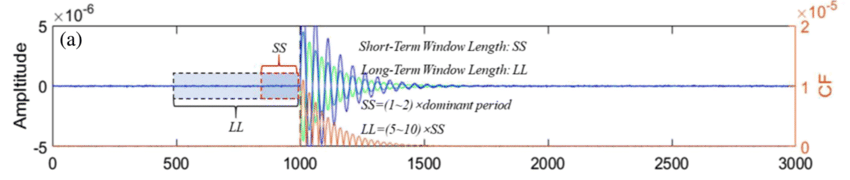

The average is to be interpreted as energy average. In the literature, different choices are made: L1 norm, L2 norm, and variance are the most common ones. The ratio between the two windows allows to quantify how the energy of the signal changes over time, and the sharpest variation corresponds to the beginning of the earthquake event. The image below, taken from [6], gives an example of how the STA/LTA algorithm is applied.

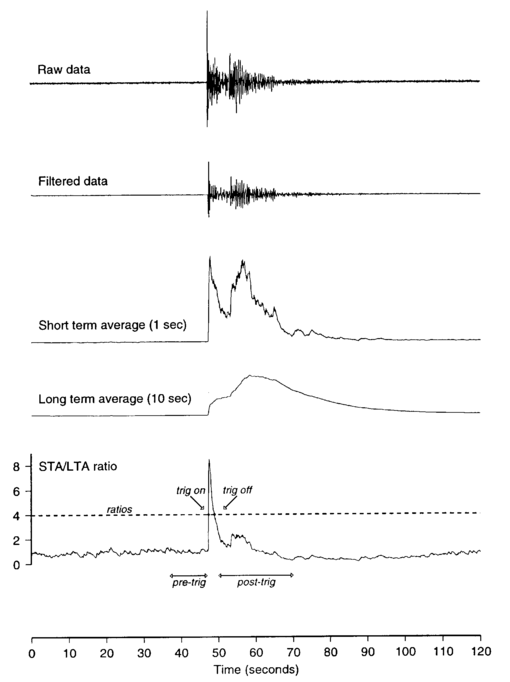

As a first task in this assignment, we will implement the STA/LTA algorithm from scratch and produce a similar plot.

**QUESTION 4a**

Looking at the spectrogram of your signal, determine which segment is the most suitable to extract the dominant period of the earthquake. Perfrom non-parameteric spectral estimation over that segment and determine the dominant frequency. Plot the resulting PSD, highlighting the dominant frequency. Compute the dominant period and choose short-term and long-term window lengths according to the criteria presented earlier.

**Hint:** the dominant period is the inverse of the frequency corresponding to the peak power spectral density.

% your code goes here 

**QUESTION 4b**

Slide the two windows one sample at the time over the whole signal as explained in the introduction, and compute separately the two energy averages as the variances of the windows. The length of the averages will be smaller than the signal length: you can ignore the initial samples for which the two windows cannot fit in the signal. Make a 4x1 subplot containing the signal, the STA, the LTA, and the STA/LTA ratio. Observe your results. Can you correctly detect the arrival of the first P-wave? At what time did it occur?

% your code goes here 

**ANSWER**

...

The advantage of the STA/LTA algorithm is that it can be easily implemented to analyze continuous recordings in real-time, as new data samples are aquired.

Next, we would like to integrate our algorithm in a prevention system that sends out an alert message when an earthquake of magnitude larger than 4.5 on the Richter scale is detected, as soon as the first P-wave arrives. To this end, we'll make use of binary hypothesis testing. The two hypotheses we want to discriminate are:

- $H_0$: an earthquake of magnitude smaller than 4.5 is taking place;

- $H_1$: an earthquake of magnitude larger than 4.5 is taking place.

Advanced detection techniques are nowadays available, but we will try to test for the two hypothesis using the STA/LTA ratio, assuming that the magnitude of the earthquake can be correctly inferred from this quantity: we divide possible ratios in two complementary regions $X_0$ and $X_1$, and assign each region to one of the two hypotheses. The Neyman-Person test allows to split the sample space in the optimal way to maximize the probability of detection given a fixed probability of false alarm. Analyzing the results we obtain, and in particular the Receiver Operating Characteristic (ROC) curve, we will assess the efficacy of the STA/LTA ratio as an indicator for earthquake detection.

**QUESTION 4c**

The table Assignment4.mat contains peak STA/LTA ratios extracted from earthquake events recorded by the same seismic observatory located in Japan, later classified based on their magnitude (magnitude less than 4.5 and magnitude larger than 4.5). Make a subplot containing the histograms for the two categories and fit a probability distribution on the data using the *histfit* function.

**Hint: **look at the *histfit* documentation to see what distributions are available.

% your code goes here 

**QUESTION 4d**

Using the distributions you determined to be appropriate in the previous exercise and the *distfit *function, compute the two probability distributions on the range [0,20] and plot them on top of each other. Next, compute the probability of detection and the probability of false alarm as a function of x and plot them against each other to obtain the Receiver Operating Characteristic (ROC) curve. Plot also the line $P_D =P_{\textrm{FA}}$. Is the STA/LTA ratio a good indicator for our detection task?

% your code goes here 

**ANSWER**

...

**QUESTION 4e**

Given $P_{\textrm{FA}} =0\ldotp 2$, compute the optimal threshold. Plot again the two probability distributions, highlight the treshold you found, and highlight the two areas corresponding to the probability of detection and the probability of false alarm.

% your code goes here 

**QUESTION 4f**

Plot again the STA/LTA ratio you obtained eariler as a function of time, together with the threshold. Should our prevention system send out the alert message? What is the probability that the upcoming earthquake is actually an event of magnitude larger than 4.5? How can we increase this probability? What is the trade-off of increasing this probability? 

% your code goes here 

**ANSWER**

...

## **References**

[1] mXrap Australian Centre for Geomechanics, [https://mxrap.com/2018/10/12/seismic-energy-and-moment/](https://mxrap.com/2018/10/12/seismic-energy-and-moment/)

[2] mXrap Australian Centre for Geomechanics, [https://mxrap.com/2018/11/03/seismic-source-parameters-quick-guide/](https://mxrap.com/2018/11/03/seismic-source-parameters-quick-guide/)

[3] Earthscope Consortium, [https://www.iris.edu/hq/](https://www.iris.edu/hq/)

[4] United States Geological Survey, Station IU MAJO, [https://earthquake.usgs.gov/monitoring/operations/stations/IU/MAJO/](https://earthquake.usgs.gov/monitoring/operations/stations/IU/MAJO/)

[5] R.X. Gao and R. Yan, 2006, *Non-stationary signal processing for bearing health monitoring, *Manufacturing Research, Vol. 1, No. 1, pp.18–40

[6] Mark K. Chang, Jan W. Kwiatkowski, Robert F. Nau, Robert M. Oliver, Karl S. Pister, 1982, *ARMA Models for Earthquake Ground Motions, *Earthquake Engineering \& Structural Dynamics, Vol. 10, No. 5, pp. 651–662

[7] Shen, Tong and Tuo, Xianguo and Li, Huailiang and Liu, Yong and Rong, Wenzheng, 2018, *A first arrival picking method of microseismic data based on single time window with window length independent, *Journal of Seismology, Vol. 22, pp. 1613–1627

[8] Guralp, [https://www.guralp.com/documents/html/MAN-D16-0001/s4.html](https://www.guralp.com/documents/html/MAN-D16-0001/s4.html)